N = 200;

## Simple self-motion from vestibular cues with varying noise:

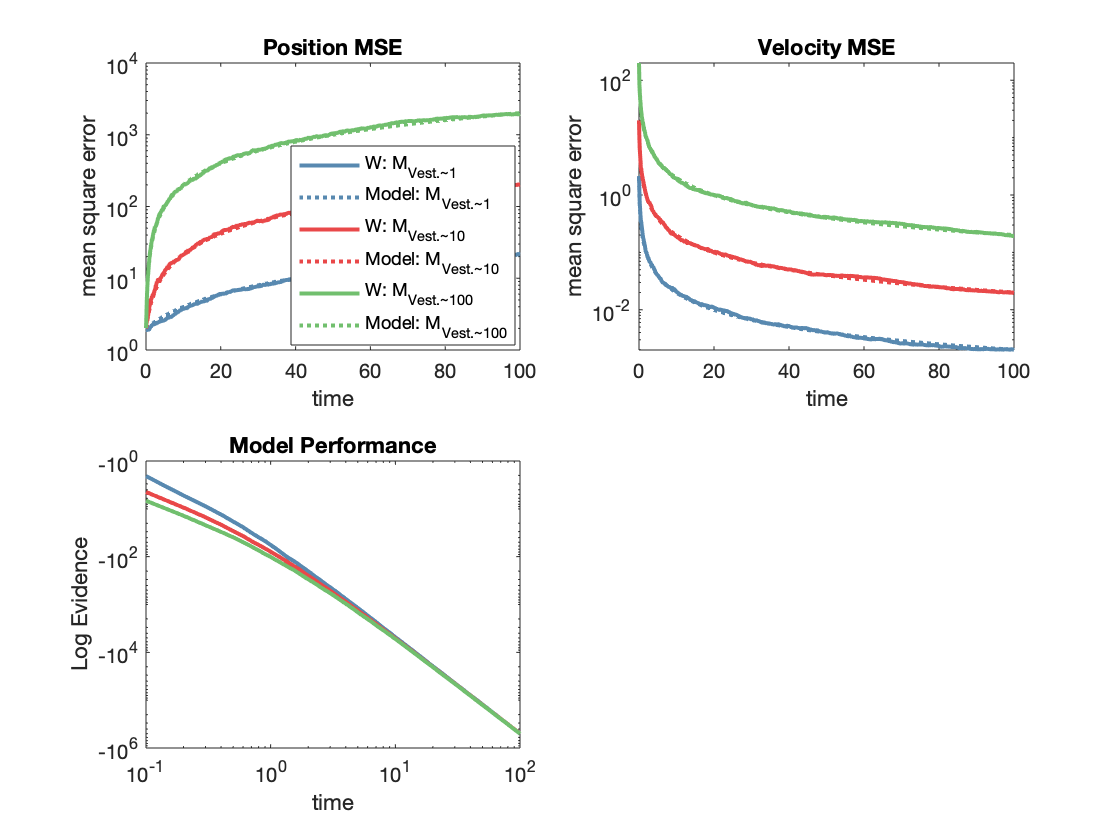

clearvars -except N
    dt = .1;
    As = {[1. 0 dt 0;
           0 1 0 dt;     
           0 0 1 0;
           0 0 0 1]};
    As(2:3) = As;
    C = [0 0 1 0;
         0 0 0 1];

    muPrior = {[0., 0, 1., 0]'};%[posX, posY, selfVelX, selfVelY]
    muPrior(2:3) = muPrior;
    initVar = {[1., 1, 1., 1]';
               [1., 1, 10., 10]';
               [1., 1, 100., 100]'};%[posX, posY, selfVelX, selfVelY]
       
    labels = {'' '' ''; 'Vest.~1' 'Vest.~10' 'Vest.~100'};

[MusLL, Vars] = runSim(As, C, muPrior, initVar, 'noiseVary', true, 'N', N, 'labels',labels);

## Self-motion with vestibular and sight cues, varying noise of vestibular cues:

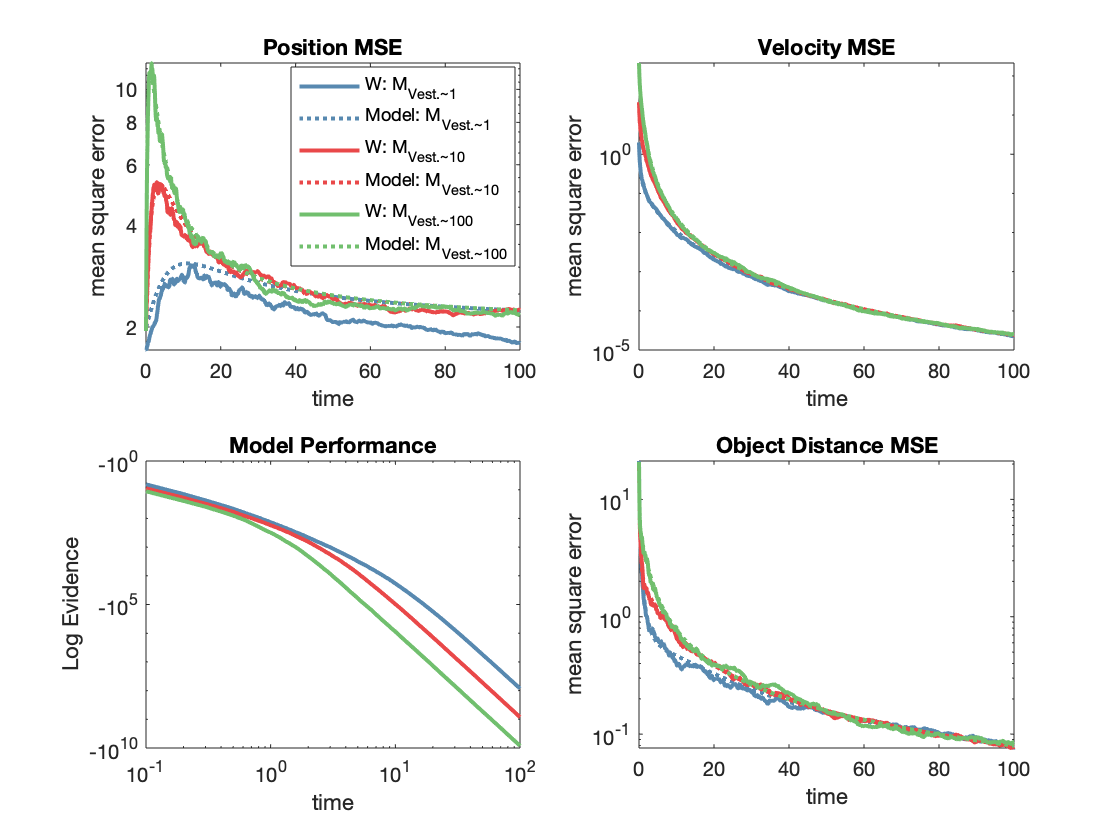

clearvars -except dt N
    As = {[1 0 0 0 dt 0;
           0 1 0 0 0 dt;
           0 0 1 0 -dt 0;
           0 0 0 1 0 -dt;
           0 0 0 0 1 0;
           0 0 0 0 0 1];};
    
    C = [0. 0 1 0 0 0;
         0. 0 0 1 0 0;
         0. 0 0 0 1 0;
         0. 0 0 0 0 1];
    
    As(2:3) = As;
    
     muPrior = {[0., 0, 10, 10, 1., 0]'};%[posX, posY, selfVelX, selfVelY]
     muPrior(2:3) = muPrior;
    initVar = {[1., 1, 10, 10, 1., 1]';
               [1., 1, 10, 10, 10., 10]';
               [1., 1, 10, 10, 100., 100]'};%[posX, posY, selfVelX, selfVelY]
   
    labels = {'' '' ''; 'Vest.~1' 'Vest.~10' 'Vest.~100'};
    
[MusLL, Vars] = runSim(As, C, muPrior, initVar, 'noiseVary', true, 'N', N, 'labels',labels);

## Self-motion with vestibular and sight cues, varying noise of site cues:

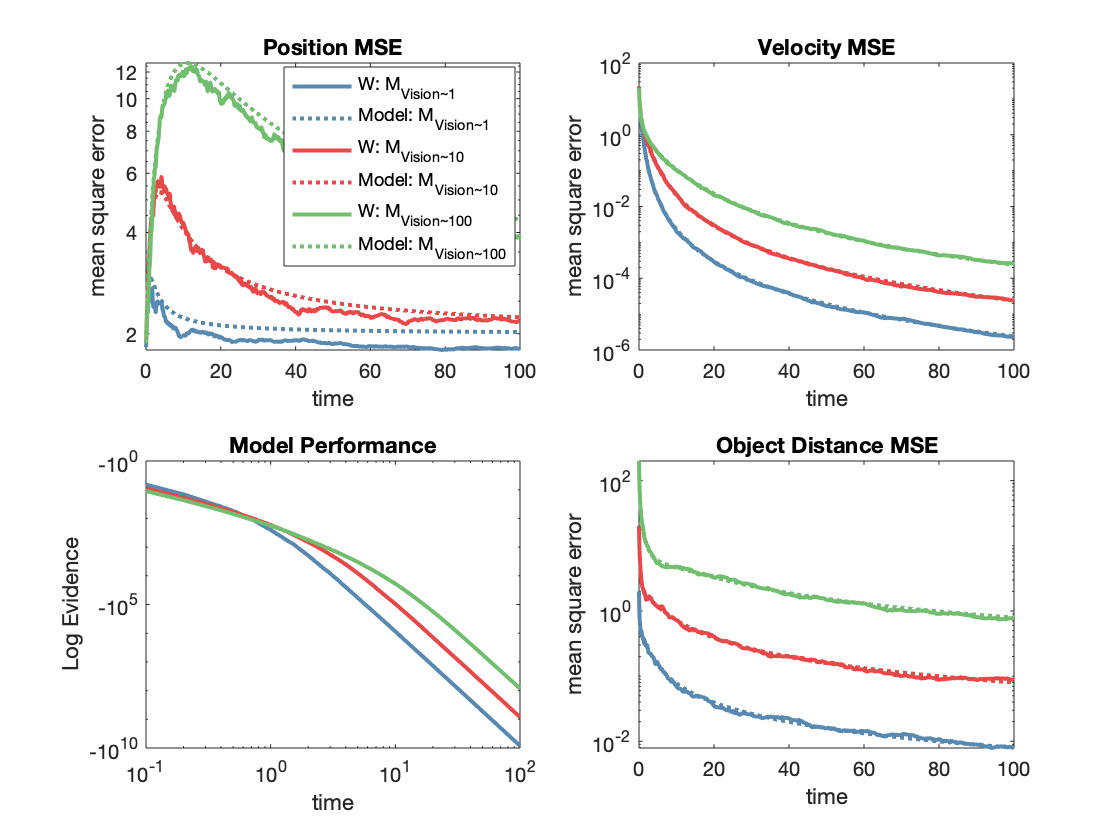

clearvars -except dt N
    As = {[1 0 0 0 dt 0;
           0 1 0 0 0 dt;
           0 0 1 0 -dt 0;
           0 0 0 1 0 -dt;
           0 0 0 0 1 0;
           0 0 0 0 0 1];};
    
    C = [0. 0 1 0 0 0;
         0. 0 0 1 0 0;
         0. 0 0 0 1 0;
         0. 0 0 0 0 1];
    
    As(2:3) = As;
    
     muPrior = {[0., 0, 10, 10, 1., 0]'};%[posX, posY, selfVelX, selfVelY]
     muPrior(2:3) = muPrior;
    initVar = {[1., 1, 1, 1, 10., 10]';
               [1., 1, 10, 10, 10., 10]';
               [1., 1, 100, 100, 10., 10]'};%[posX, posY, selfVelX, selfVelY]
              
    labels = {'' '' ''; 'Vision~1' 'Vision~10' 'Vision~100'};

[MusLL, Vars] = runSim(As, C, muPrior, initVar, 'noiseVary', true, 'N', N, 'labels',labels);

## Self- and object-motion with vestibular and sight cues, varying noise of vestibular cues:

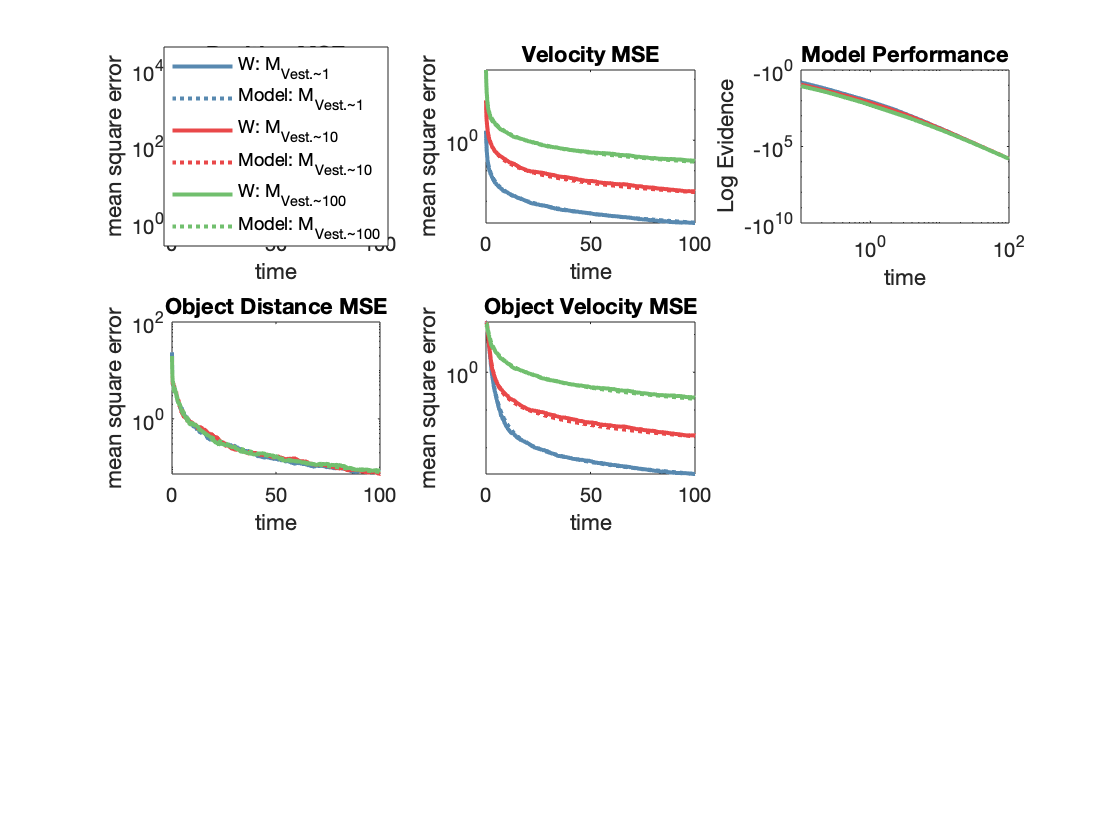

clearvars -except dt N
    
    As = {[1. 0 0 0 0 0 dt 0;
          0 1 0 0 0 0 0 dt;
          0 0 1 0 dt 0 -dt 0;
          0 0 0 1 0 dt 0 -dt;
          0 0 0 0 1 0 0 0;
          0 0 0 0 0 1 0 0;
          0 0 0 0 0 0 1 0;
          0 0 0 0 0 0 0 1]};
    As(2:3) = As;
    
    C = [0. 0 1 0 0 0 0 0;
         0. 0 0 1 0 0 0 0;
         0. 0 0 0 0 0 1 0;
         0. 0 0 0 0 0 0 1];
     
    muPrior = {[0., 0, 10., 10, 0., 1, 1., 0]'};%[posX, posY, objDistX, objDistY, objVelX, objVelY, selfVelX, selfVelY]
    muPrior(2:3) = muPrior;
    initVar = {[1., 1, 10., 10, 10., 10, 1., 1]';
               [1., 1, 10., 10, 10., 10, 10., 10]';
               [1., 1, 10., 10, 10., 10, 100., 100]'};%[posX, posY, objDistX, objDistY, objVelX, objVelY, selfVelX, selfVelY]

    labels = {'' '' ''; 'Vest.~1' 'Vest.~10' 'Vest.~100'};

[MusLL, Vars] = runSim(As, C, muPrior, initVar, 'noiseVary', true, 'N', N, 'labels',labels);

## Self- and object-motion with vestibular and sight cues, varying noise of sight cues:

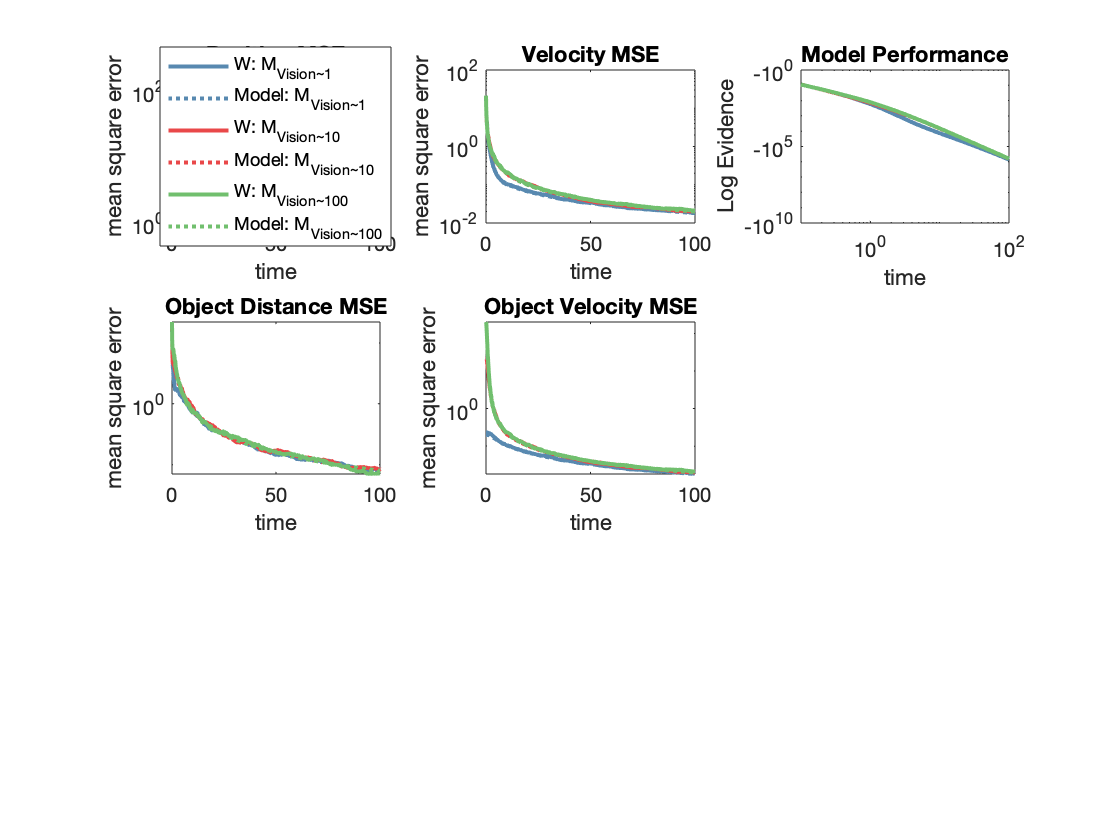

clearvars -except dt N
    
    As = {[1. 0 0 0 0 0 dt 0;
          0 1 0 0 0 0 0 dt;
          0 0 1 0 dt 0 -dt 0;
          0 0 0 1 0 dt 0 -dt;
          0 0 0 0 1 0 0 0;
          0 0 0 0 0 1 0 0;
          0 0 0 0 0 0 1 0;
          0 0 0 0 0 0 0 1]};
    As(2:3) = As;
    
    C = [0. 0 1 0 0 0 0 0;
         0. 0 0 1 0 0 0 0;
         0. 0 0 0 0 0 1 0;
         0. 0 0 0 0 0 0 1];
     
    muPrior = {[0., 0, 10., 10, 0., 1, 1., 0]'};%[posX, posY, objDistX, objDistY, objVelX, objVelY, selfVelX, selfVelY]
    muPrior(2:3) = muPrior;
    initVar = {[1., 1, 10., 10, .1, .1, 10., 10]';
               [1., 1, 10., 10, 10., 10, 10., 10]';
               [1., 1, 10., 10, 100., 100, 10., 10]'};%[posX, posY, objDistX, objDistY, objVelX, objVelY, selfVelX, selfVelY]

    labels = {'' '' ''; 'Vision~1' 'Vision~10' 'Vision~100'};

[MusLL, Vars] = runSim(As, C, muPrior, initVar, 'noiseVary', true, 'N', N, 'labels',labels);

## Causal inference over Kalman Models: Still--> No object motion & Moving--> Object motion

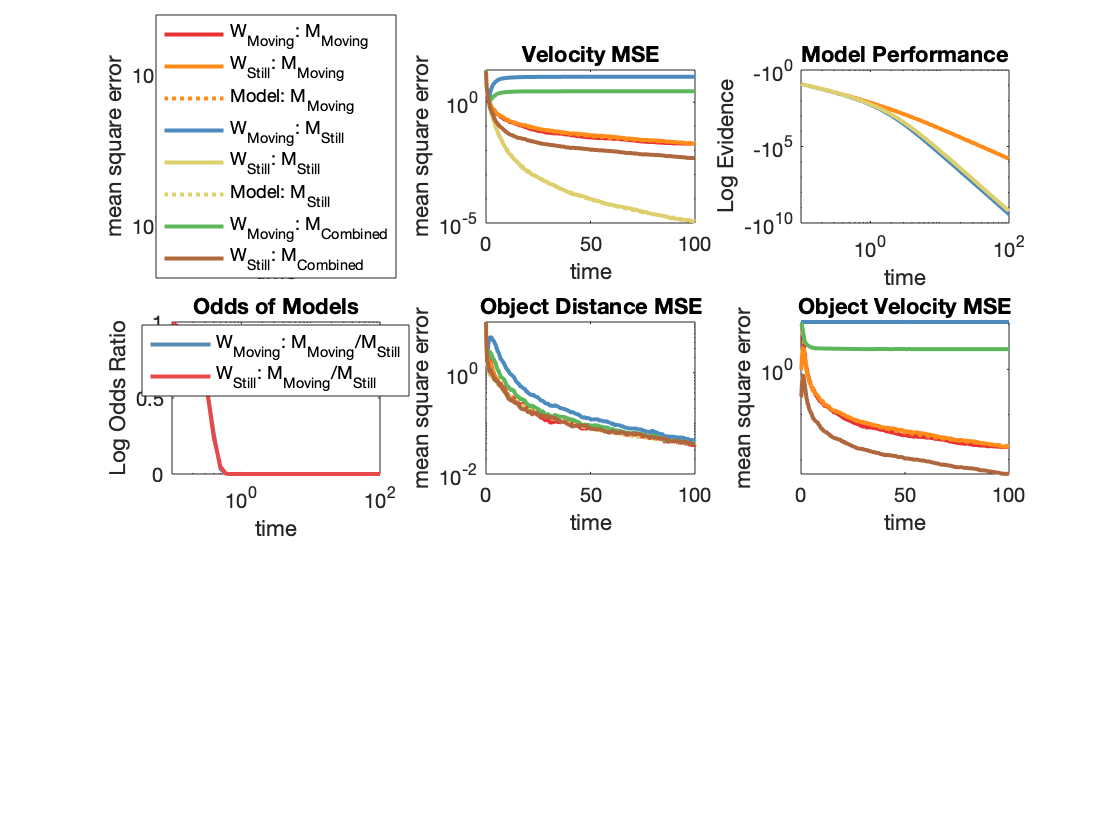

clearvars -except dt N

A1 = [1. 0 0 0 0 0 dt 0;
      0 1 0 0 0 0 0 dt;
      0 0 1 0 dt 0 -dt 0;
      0 0 0 1 0 dt 0 -dt;
      0 0 0 0 1 0 0 0;
      0 0 0 0 0 1 0 0;
      0 0 0 0 0 0 1 0;
      0 0 0 0 0 0 0 1];

 A2 = [1. 0 0 0 0 0 dt 0;
       0 1 0 0 0 0 0 dt;
       0 0 1 0 0 0 -dt 0;
       0 0 0 1 0 0 0 -dt;
       0 0 0 0 1 0 0 0;
       0 0 0 0 0 1 0 0;
       0 0 0 0 0 0 1 0;
       0 0 0 0 0 0 0 1];

As{1} = A1;
As{2} = A2;


C = [0. 0 1 0 0 0 0 0;
     0. 0 0 1 0 0 0 0;
     0. 0 0 0 0 0 1 0;
     0. 0 0 0 0 0 0 1];
muPrior = {[0., 0, 10., 10, 0., 1, 1., 0]';
           [0., 0, 10., 10, 0., 0, 1., 0]'};%[posX, posY, objDistX, objDistY, objVelX, objVelY, selfVelX, selfVelY]
initVar = {[1., 1, 5., 5, 5., 5, 10., 10]';
           [1., 1, 5., 5, 0., 0, 10., 10]'};%[posX, posY, objDistX, objDistY, objVelX, objVelY, selfVelX, selfVelY]


emitVar{1} = [1., 1, 5., 5, 5., 5, 10., 10]';%[memoryX, memoryY, visionX, visionY, objInertiaX, objInertiaY, vestibularX, vestibularY]
emitVar{2} = [1., 1, 5., 5, 0., 0, 10., 10]';%[memoryX, memoryY, visionX, visionY, objInertiaX, objInertiaY, vestibularX, vestibularY]
muInit{1} = [0., 0, 10., 10, 0., 1, 1., 0]';%[posX, posY, objDistX, objDistY, objVelX, objVelY, selfVelX, selfVelY]
muInit{2} = [0., 0, 10., 10, 0., 0, 1., 0]';%[posX, posY, objDistX, objDistY, objVelX, objVelY, selfVelX, selfVelY]
[MusLL, Vars] = runSim(As, C, muPrior, initVar, 'emitVar', emitVar, 'muInit', muInit, 'noiseVary', false, 'agnt', true,'N', N);

## Log odds ratios of Kalman Models used by agent

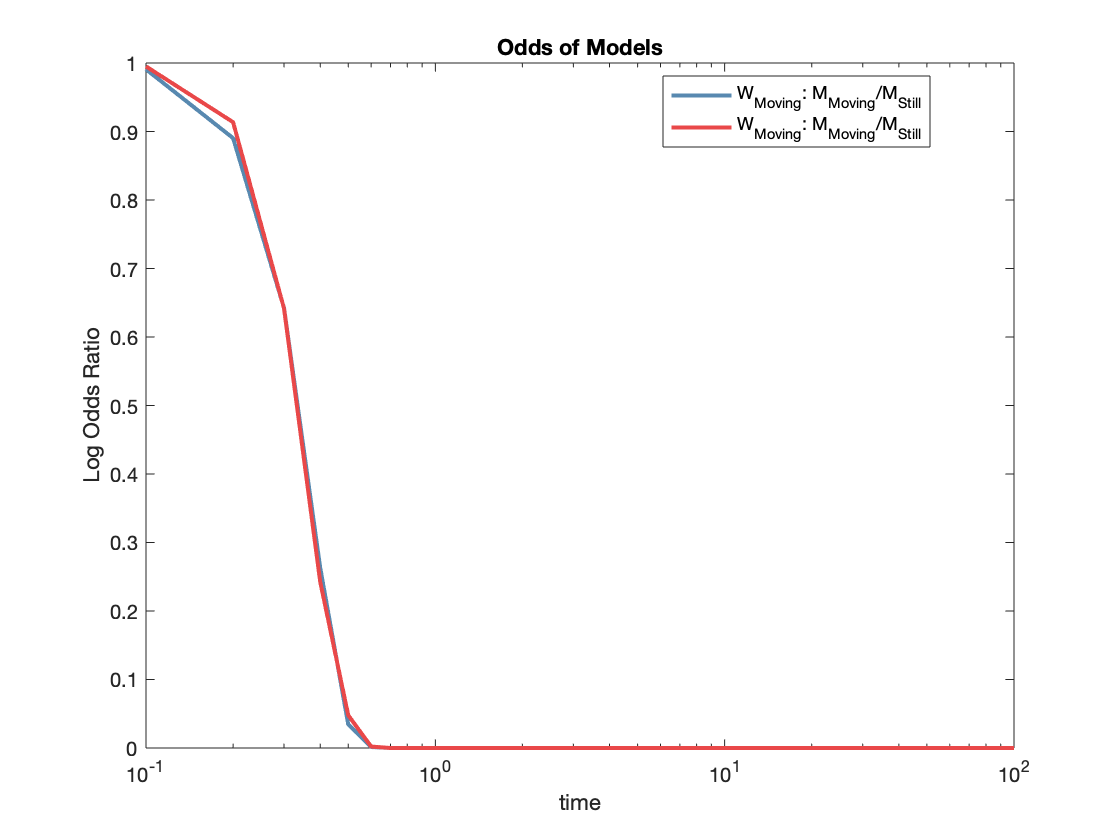

plotLogOdds(MusLL, [0:size(MusLL,4)-1]*dt, {'Moving', 'Still', ''; 'Moving', 'Still', 'Combined'});

## Causal inference Agent using Kalman Models to track an object with Markovian switches between motion and stillness

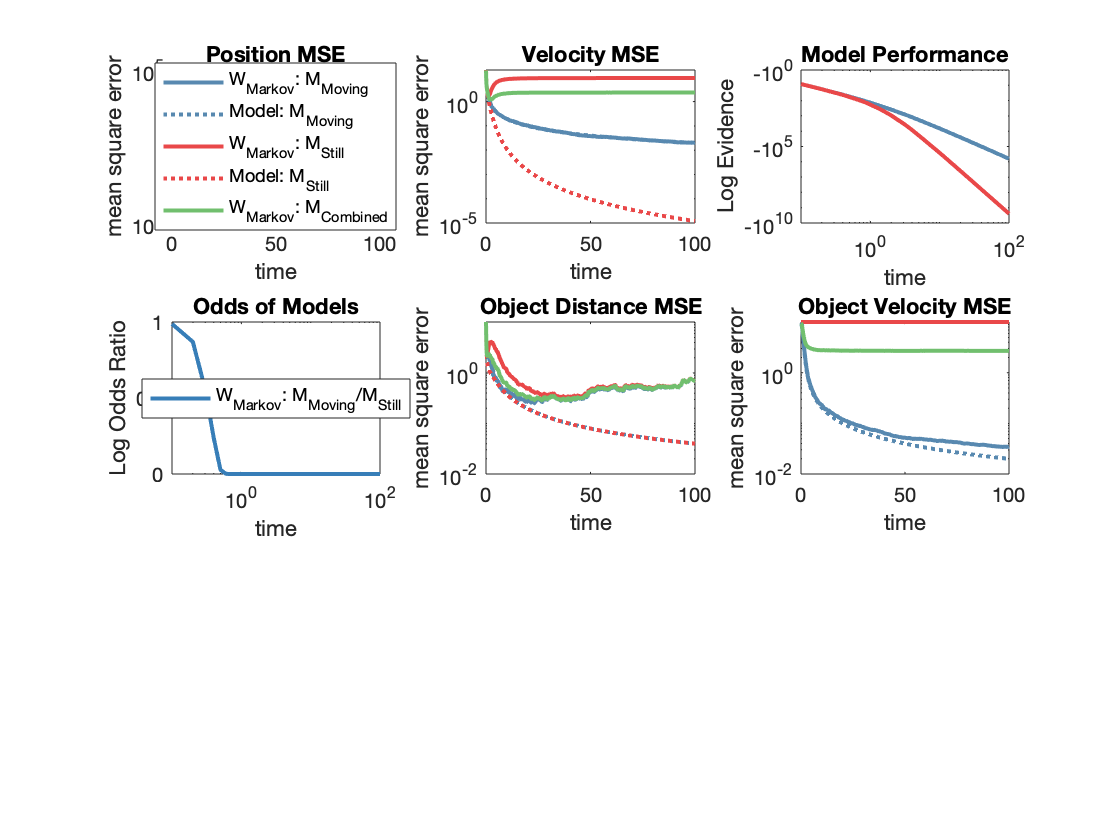

clearvars -except dt N

A1 = [1. 0 0 0 0 0 dt 0;
      0 1 0 0 0 0 0 dt;
      0 0 1 0 dt 0 -dt 0;
      0 0 0 1 0 dt 0 -dt;
      0 0 0 0 1 0 0 0;
      0 0 0 0 0 1 0 0;
      0 0 0 0 0 0 1 0;
      0 0 0 0 0 0 0 1];

 A2 = [1. 0 0 0 0 0 dt 0;
       0 1 0 0 0 0 0 dt;
       0 0 1 0 0 0 -dt 0;
       0 0 0 1 0 0 0 -dt;
       0 0 0 0 1 0 0 0;
       0 0 0 0 0 1 0 0;
       0 0 0 0 0 0 1 0;
       0 0 0 0 0 0 0 1];

As{1} = A1;
As{2} = A2;


C = [0. 0 1 0 0 0 0 0;
     0. 0 0 1 0 0 0 0;
     0. 0 0 0 0 0 1 0;
     0. 0 0 0 0 0 0 1];
muPrior = {[0., 0, 10., 10, 0., 1, 1., 0]';
           [0., 0, 10., 10, 0., 0, 1., 0]'};%[posX, posY, objDistX, objDistY, objVelX, objVelY, selfVelX, selfVelY]
initVar = {[1., 1, 5., 5, 5., 5, 10., 10]';
           [1., 1, 5., 5, 0., 0, 10., 10]'};%[posX, posY, objDistX, objDistY, objVelX, objVelY, selfVelX, selfVelY]


emitVar{1} = [1., 1, 5., 5, 5., 5, 10., 10]';%[memoryX, memoryY, visionX, visionY, objInertiaX, objInertiaY, vestibularX, vestibularY]
emitVar{2} = [1., 1, 5., 5, 0., 0, 10., 10]';%[memoryX, memoryY, visionX, visionY, objInertiaX, objInertiaY, vestibularX, vestibularY]
muInit{1} = [0., 0, 10., 10, 0., 1, 1., 0]';%[posX, posY, objDistX, objDistY, objVelX, objVelY, selfVelX, selfVelY]
muInit{2} = [0., 0, 10., 10, 0., 0, 1., 0]';%[posX, posY, objDistX, objDistY, objVelX, objVelY, selfVelX, selfVelY]

[MusLL, Vars] = runSim(As, C, muPrior, initVar, 'emitVar', emitVar, 'muInit', muInit, 'noiseVary', false, 'agnt', true, 'Markov', true, 'N', N, 'labels',{'Markov','',''; 'Moving', 'Still', 'Combined'});

## With abrupt cost function:

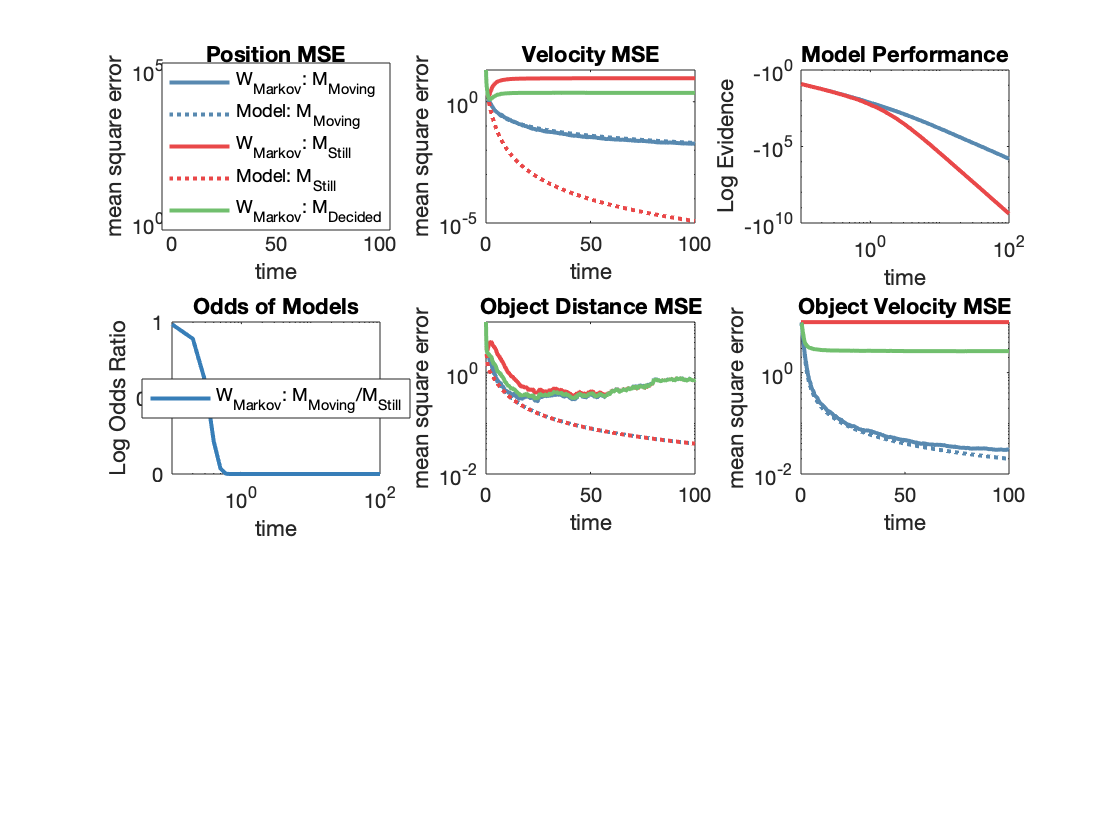

[MusLL, Vars] = runSim(As, C, muPrior, initVar, 'emitVar', emitVar, 'muInit', muInit, 'noiseVary', false, 'agnt', true, 'Markov', true, 'N', N, 'labels',{'Markov','',''; 'Moving', 'Still', 'Decided'}, 'CostFun','Abrupt');

## With Mahal-abrupt cost function:

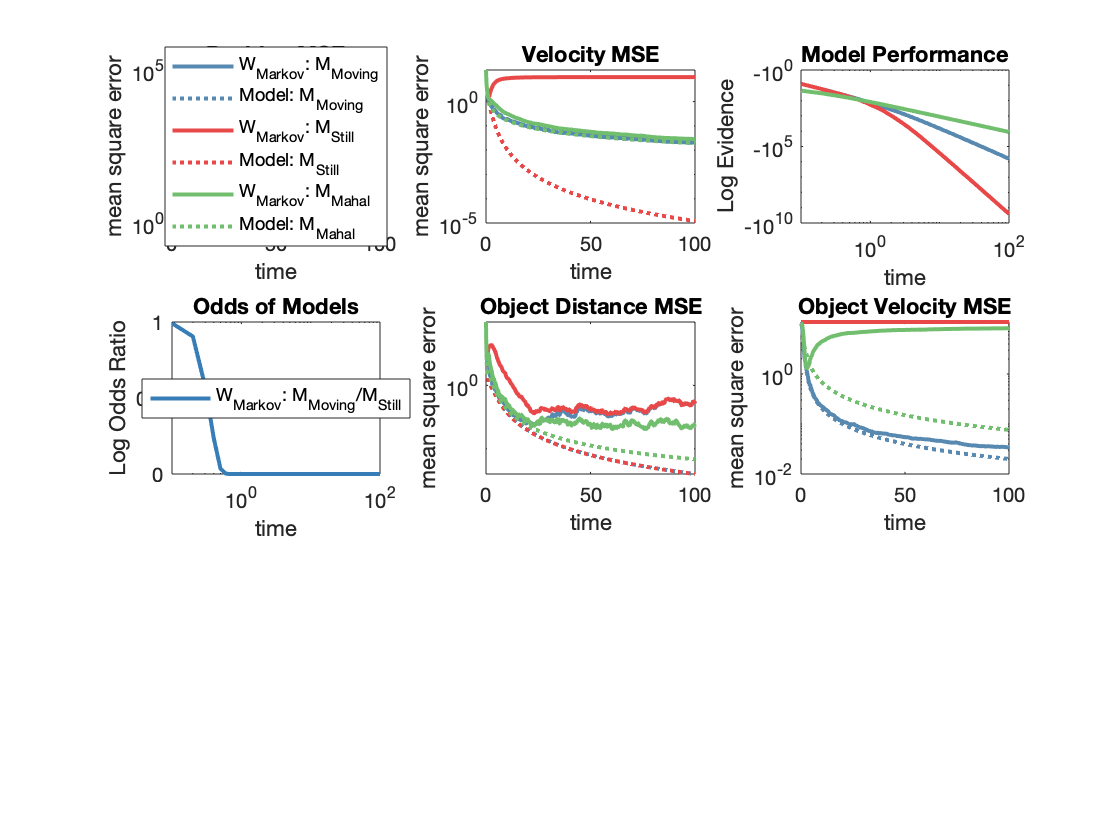

[MusLL, Vars] = runSim(As, C, muPrior, initVar, 'emitVar', emitVar, 'muInit', muInit, 'noiseVary', false, 'agnt', true, 'Markov', true, 'N', N, 'labels',{'Markov','',''; 'Moving', 'Still', 'Mahal'}, 'CostFun','Mahal');